`Erfan Panahi 810186369`

# ***Blind Source Separation ***

## **Homework #1**

`Problem 1.`

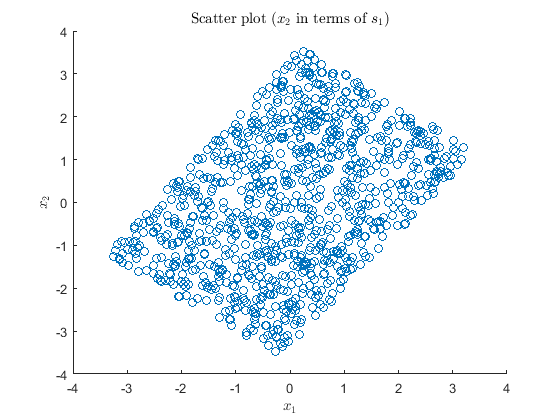

clear
s1 = unifrnd(-3,3,[1,1000]);
s2 = unifrnd(-2,2,[1,1000]);
S = [s1;s2];
A = [0.6 0.8;
     0.8 -0.6];
X = A*S;
x1 = X(1,:); 
x2 = X(2,:);
scatter(x1,x2);
title('Scatter plot ($x_2$ in terms of $s_1$)','Interpreter','latex');
xlabel('$x_1$','Interpreter','latex');
ylabel('$x_2$','Interpreter','latex');

`Problem 2.`

[i1,j1] = max(x1); I1 = X(:,j1); 
[i2,j2] = min(x1); I2 = X(:,j2); 
[i3,j3] = max(x2); I3 = X(:,j3); 
[i4,j4] = min(x2); I4 = X(:,j4);
a1 = I1 - I4; % or a1 = I1 - I3;
a2 = I4 - I2; % or a2 = I2 - I3;
% now we normalize the size of the vectors
a1 = a1/sqrt(a1(1)^2+a1(2)^2);
a2 = a2/sqrt(a2(1)^2+a2(2)^2);
Beta = [a1 a2]

Beta =     0.5892    0.8053
    0.8080   -0.5928


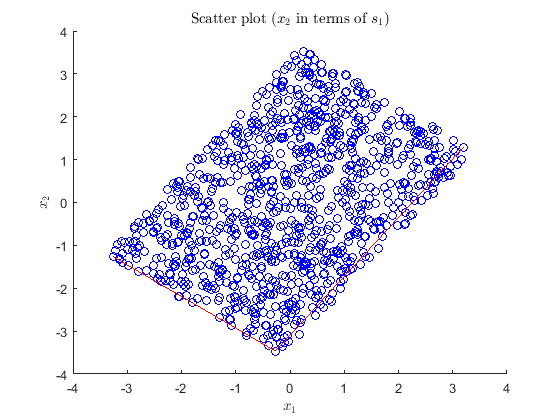

hold on
scatter(x1,x2,'b');
plot([I1(1),I4(1),I2(1)],[I1(2),I4(2),I2(2)],'r');
title('Scatter plot ($x_2$ in terms of $s_1$)','Interpreter','latex');
xlabel('$x_1$','Interpreter','latex');
ylabel('$x_2$','Interpreter','latex');
hold off

`Problem 3.`

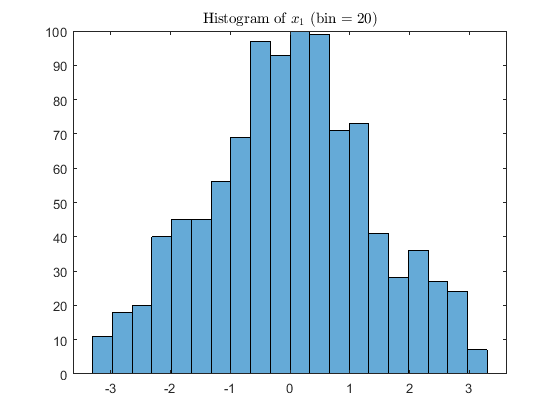

histogram(x1,20);
title('Histogram of $x_1$ (bin = 20)','Interpreter','latex');

`Problem 4.`

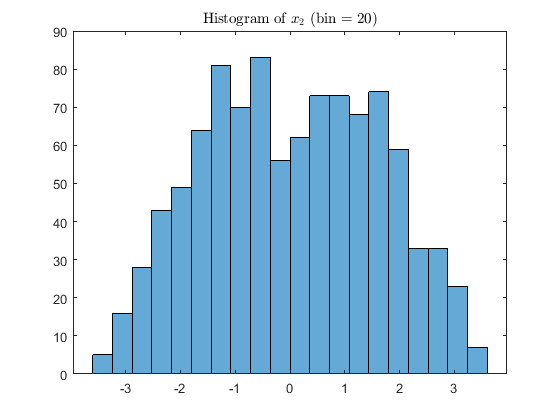

histogram(x2,20);
title('Histogram of $x_2$ (bin = 20)','Interpreter','latex');